## Analysis Pipeline for PEP WP-4 EEG Project

### House keeping

clc; clear; close all;%dbstop if error;
cfg = struct;
d = struct;

% add functions folder to path
cfg.functionPath = fullfile(pwd,'utilities');
addpath(genpath(cfg.functionPath))

### Define to-be-analyzed subjects

cfg.subNums = [101:106, 109:113, 115:117, 119:122, 124, 126:127, 130, 140]; % 118 did not finish the experiment
cfg = defaultCfg(cfg);

### Preprocessing

disp(['Running pre-processing...' newline]);
preprocess_EEG(cfg);

### Decoding

disp(['Running decoding...' newline]);
decoding_EEG(cfg);

### Individual decoding accuracies

disp(['Running individual decoding...' newline]);
individual_decoding_accuracies(cfg);

### Pairwise decoding

cfg.plotting = false;
disp(['Running pairwise decoding...' newline]);

Running pairwise decoding...



[d.pairRep, cfg] = PairwiseTPLDAclassifier(cfg);

RDM for sub-101 already exists
RDM for sub-102 already exists
RDM for sub-103 already exists
RDM for sub-104 already exists
RDM for sub-105 already exists
RDM for sub-106 already exists
RDM for sub-109 already exists
RDM for sub-110 already exists
RDM for sub-111 already exists
RDM for sub-112 already exists
RDM for sub-113 already exists
RDM for sub-115 already exists
RDM for sub-116 already exists
RDM for sub-117 already exists
RDM for sub-119 already exists
RDM for sub-120 already exists
RDM for sub-121 already exists
RDM for sub-122 already exists
RDM for sub-124 already exists
RDM for sub-126 already exists
RDM for sub-127 already exists
RDM for sub-130 already exists
RDM for sub-140 already exists


### ISC of representation

cfg.plotting = true;
cfg.regressOutMean = false;
disp(['Running ISC...' newline]);

Running ISC...



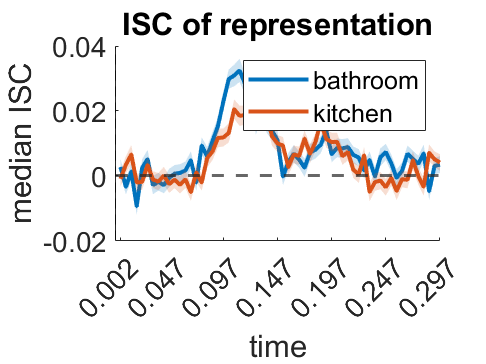

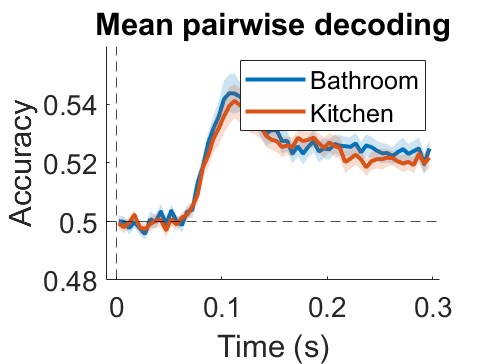

d = getISCofRespresentation(cfg, d);

### ISC of representation with regressOutMean

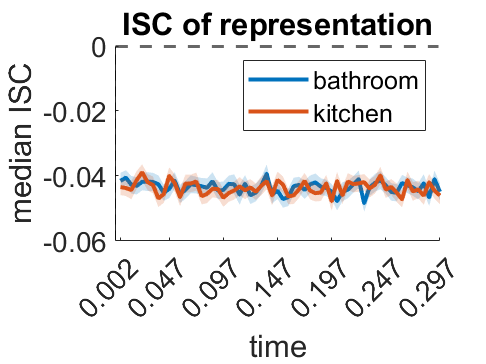

cfg.regressOutMean = true;
cfg.dissimilarity = true;
cfg.ISC_types = {'pairRep'};
cfg.correlation_type = 'spearman';
cfg.plotting = false;
cfg.new_figure = false;
d = getISCofRespresentation(cfg, d);

### Get inter-subject similarity on drawings

cfg.dnn = 'vgg16_imagenet';
cfg.layer_type = 'late';
cfg.correlation_type = 'Spearman';
cfg.dissimilarity = true;
cfg.plot_rdm = true;

% Create output directory if wanted
output_dir = fullfile(pwd, '..', 'dnn_features');
if exist(output_dir, 'dir')
    rmdir(output_dir, 's');
end

% get images
cfg.analysis_names = {'typical', 'control','photos'};
images = load_images(cfg);

% layer similiarity
[d, cfg] = get_dnn_layer_similarity(d, images, cfg);
  
% % typical images
% cfg.analysis_names = {'typical'};
% [d, cfg] = get_dnn_layer_similarity(d, images, cfg);
% 
% % control images
% cfg.analysis_names = 'control';
% [d, cfg] = get_dnn_layer_similarity(d, images, cfg);
% 
% % photos
% cfg.analysis_names = 'photos';
% [d, cfg] = get_dnn_layer_similarity(d, images, cfg);

% filter for included subjects
d = filterCurrentSubs(d, cfg);


### Compare ISC from drawings with ISC of neural representations 

 Start evaluating predictor RDMs
Predictor RDMs evaluated
 Start evaluating predictor RDMs
Predictor RDMs evaluated


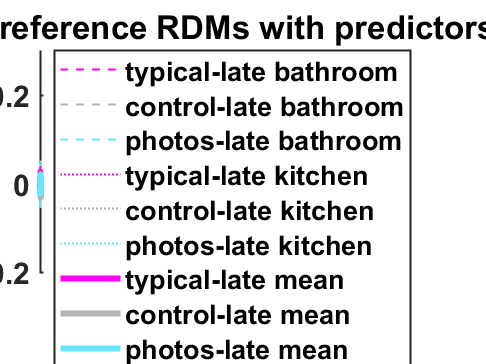

% preparation
cfg.partial_cor = true;
cfg.plotting = true;
cfg.predictor_RDMs = {'typical_late', 'control_late', 'photos_late'};
cfg.RDM_to_partial_out = cfg.predictor_RDMs;
cfg.dnns = {'vgg16_imagenet'};
cfg.show_single_cate = true;
cfg.partial_correlation_type = 'pearson';

% run
d = compare_tp_RDMs_to_predictor_RDMs(d, cfg);

Get inter-subject similarity on timecourses

% % preparation
% cfg.dissimilarity = true;
% cfg.plotting = true;
% 
% % get timecourses (average Voxels for each ROI)
% cfg.skipIfExists = false;
% cfg.smoothing = false; 
% cfg.saveWholeBrain = false;
% cfg.cutTargets = false;
% 
% % get ISC from timecourses
% cfg.regressOutMean = false;
% cfg.detrend = true;
% cfg.correlation_type = 'Pearson';
% d = neural_timecourse_intersub_cor(d, cfg);
% 
% % get split-half reliability for ISC
% d = splithalfReliabilityISC(d, cfg);

Compare ISC from drawings with timecourse ISC

% % preparation
% cfg.partial_cor = true;
% cfg.plot_rdm = false;
% cfg.predictor_RDMs = {'typical_late', 'control_late', 'photos_late'};
% cfg.RDM_to_partial_out = cfg.predictor_RDMs;
% cfg.rois_of_interest = {'V1', 'V2', ...
%     'LOC', 'PPA', 'TOS', 'RSC', 'LPFC',...
%     'motorCortex', 'S1', 'auditoryCortex'};
% cfg.dnns = {'vgg16_imagenet'};
% cfg.plot_type = 'bar';
% cfg.show_single_cate = true;
% cfg.permutation_test = true;
% cfg.n_permutations = 1000;
% cfg.permutation_type = 'row_col_shuffle_ref';
% cfg.ISC_type = 'timecourseRDM';
% cfg.partial_correlation_type = 'pearson';
% 
% d = compare_roi_RDMs_to_predictor_RDMs(d, cfg);

Get neural RDMs of single stimuli for each subject

% % % % preparations
% % % cfg.rois = {'wV1.nii', 'wV2.nii',...
% % %     'wLOC.nii', 'wRSC.nii',...
% % %     'wPPA.nii', 'wTOS.nii',...
% % %  'wS1.nii', 'wauditoryCortex.nii'};
% % % cfg.map = 't';
% % % 
% % % % run RDM based on simple correlations
% % % d.simgpleRDMresults = Copy_of_SimpleRDM(cfg.subNums, cfg.nTrials, cfg.map, cfg.rois)

% % % Get inter-subject similarity on single stimulus RDMs
% % % % preparation
% % % cfg.map = 't';
% % % cfg.plotting = false;
% % % 
% % % % run neural ISC script
% % % [d] = neural_intersub_cor(d, cfg)
% % % 

Compare ISC from drawings with neural ISC

% % % % preparation
% % % cfg.partial_cor = 1;
% % % cfg.plot_rdm = 0;
% % % cfg.RDM_to_partial_out = {'Typical Images vgg16_imagenet Late', 'Control Images vgg16_imagenet Late'};
% % % cfg.predictor_RDMs = {'typical_late', 'control_late'};
% % % cfg.rois_of_interest = {'wV1', 'wLOC', 'wPPA', ...
% % %     'wTOS', 'wRSC', 'wmotorCortex', 'wS1', 'wauditoryCortex'};
% % % cfg.dnns = {'vgg16_imagenet'};
% % % cfg.plot_type = 'bar';
% % % cfg.show_single_cate = 1;
% % % cfg.permutation_test = 1;
% % % cfg.n_permutations = 1000;
% % % cfg.permutation_type = 'row_col_shuffle_pred';
% % % 
% % % cfg.partial_correlation_type = 'pearson';
% % % 
% % % d = compare_roi_RDMs_to_predictor_RDMs(d, cfg);

End Message

% % % finished!
% % disp([ ...
% %     newline, ...
% %     '#########################', ...
% %     newline, ...
% %     '####### ALL DONE! #######', ...
% %     newline, ...
% %     '#########################', ...
% %     newline ...
% %     ]);